# Getting the CPSDM from data through Blackman-Tukey estimator

## Introduction

In this tutorial you will learn how to estimate the CPSDM of a random process from a multivariate time series through the Blackman-Tukey estimator. 

The dataset employed in this tutorial is '*datasets/dataset_02_VAR_2V*', which includes a synthetic 2-variate zero mean time series generated with a restricted VAR(5) model, and the true spectrum of the VAR model. This allows comparison between the estimated CPSDM and the true CPSDM. 

## Tutorial

First of all, add mVARbox to path, set the tutorial parameters.

setmVARboxPath

mVARbox path has been added to MATLAB path



clear
clc
close all


%%% Parameters

N_f             = 100;      % number of elements of the frequency vector

M               = 50;       % máximum lag considered for the estimation
                            % of the autocovariance function

method  = 'biased_matlab';  % Method for estimating the autocovariance function.
                            % For a list of estimation methods, see function 
                            % 'initialise_gamma'.                            
                            % Leave empty [] for default value (see function
                            % 'fun_default_value').

window_name = 'Hamming';    % Name of the window applied to the estimated 
                            % autocovariance function.
                            % For a list of window names, see function
                            % 'initialise_window'. 
                            % Leave empty [] for default value (see function
                            % 'fun_default_value').

% %%% Plot parameters
font_size       = 18;
figure_position = [0 0 1000 400];
CC              = colororder;
color_estimated = CC(5,:);
color_true      = CC(4,:);

Load from the dataset the data (in the form of a `data` object) and the true CPSDM (in the form of a CPSDM object) of the related VAR model. For details related to the fields of these objects, see functions `initialise_data` and `initialise_CPSDM`.

load dataset_02_VAR_2V data_VAR CPSDM_VAR 

Have a look at the time series considered. 

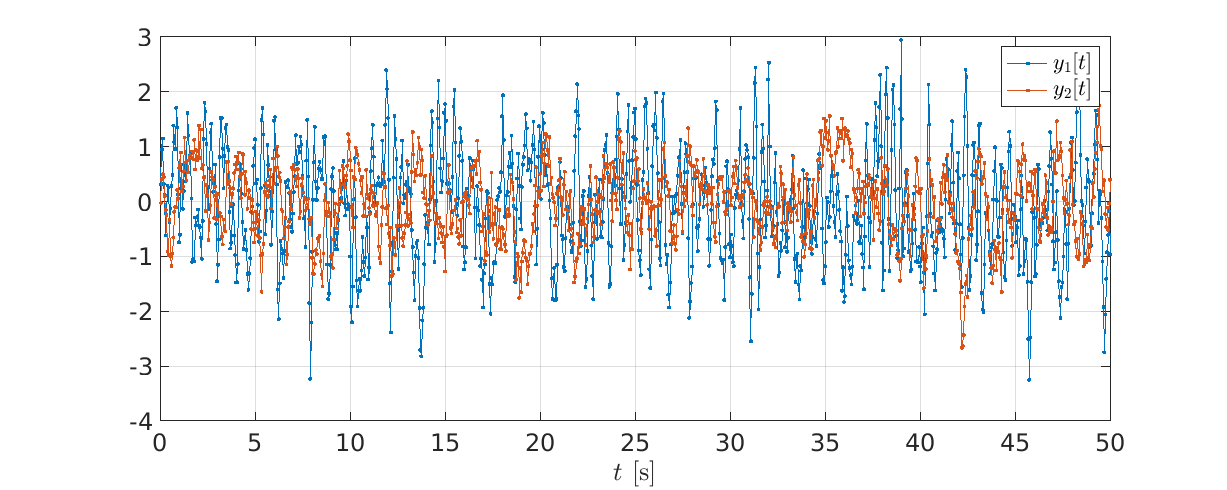

figure

x = data_VAR.x_values;
y = data_VAR.y_values;
plot(x,y,'.-')

grid on
xlabel('$t$ [s]','Interpreter','latex')
xlim([0 data_VAR.x_values(end)])
legend('$y_1[t]$','$y_2[t]$','interpreter','latex')

set(gca,'fontsize',font_size)

set(gcf,'position',figure_position)

Note the sampling time and the time span of the data. They are useful to define the maximum frequency, $f_{max}$, and the minimum frequency, $f_{min}$. The frequency vector to evaluate the sample spectrum, `f_vector`, will be defined within this frequency range.

delta_t     = data_VAR.x_parameters.delta_x;   % seconds
t_sim       = delta_t*data_VAR.x_parameters.N; % seconds

f_max       = 1/(2*delta_t);
f_min       = 1/t_sim;

f_vector    = linspace(f_min,f_max,N_f);

Initialise a CPSDM object  with the fields required by function `get_CPSDM_data_BT`. 

CPSDM0 = initialise_CPSDM('x_values', f_vector);

Initialise a gamma object  with the fields required by function `get_CPSDM_data_BT`.

gamma_fun0 = initialise_gamma('M', M, 'method', method);

Initialise a `window` object with the fields required by function `get_CPSDM_data_BT`.

window = initialise_window('name',window_name);

Compute the CPSDM of the data.

[CPSDM_BT] = get_CPSDM_data_BT(data_VAR, CPSDM0, gamma_fun0, window);

Plot the obtained CPSDM together with the true spectrum. Note that the cross spectrum is, in general, complex valued. Thus, first plot is for real part (co-spectrum), and second plot is for imaginary part (quad-spectrum).

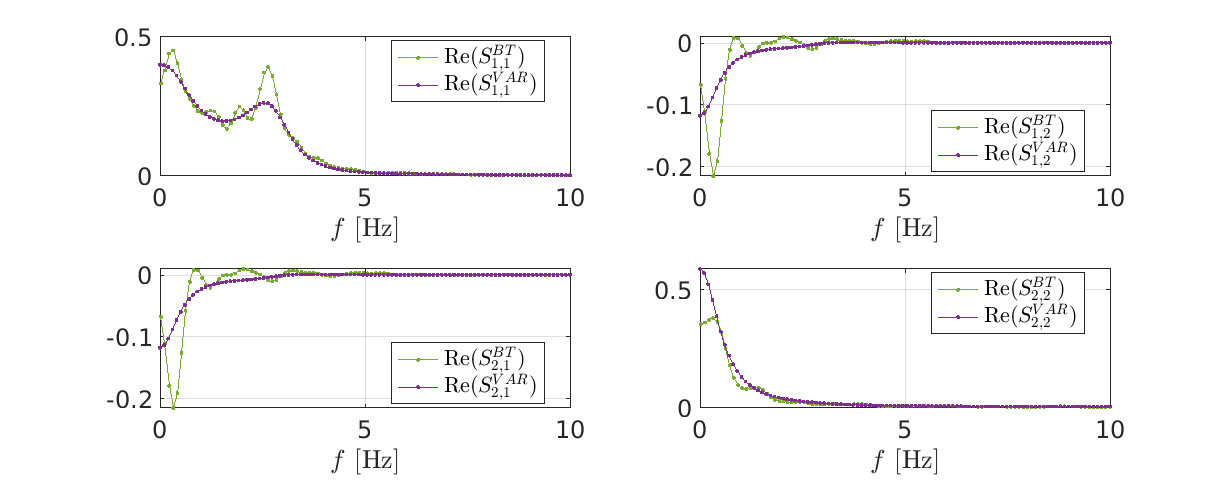

k = CPSDM_BT.k;


% Co-spectrum

figure(1)

for ii = 1:k

    for jj = 1:k

        subplot(k,k,(ii-1)*k+jj)

        x = CPSDM_BT.x_values;
        y = real(squeeze(CPSDM_BT.y_values(ii,jj,:)));
        plot(x,y,'.-','color',color_estimated)

        hold on

        x = CPSDM_VAR.x_values;
        y = real(squeeze(CPSDM_VAR.y_values(ii,jj,:)));
        plot(x,y,'.-','color',color_true)
    
        leg_BT = sprintf('Re$(S^{BT}_{%d,%d})$',ii,jj);
        leg_VAR = sprintf('Re$(S^{VAR}_{%d,%d})$',ii,jj);
        legend({leg_BT,leg_VAR},...
               'Interpreter','latex',...
               'Location','best')

        grid on
        xlabel('$f$ [Hz]','Interpreter','latex')
        set(gca,'fontsize',font_size)
        
    end

end

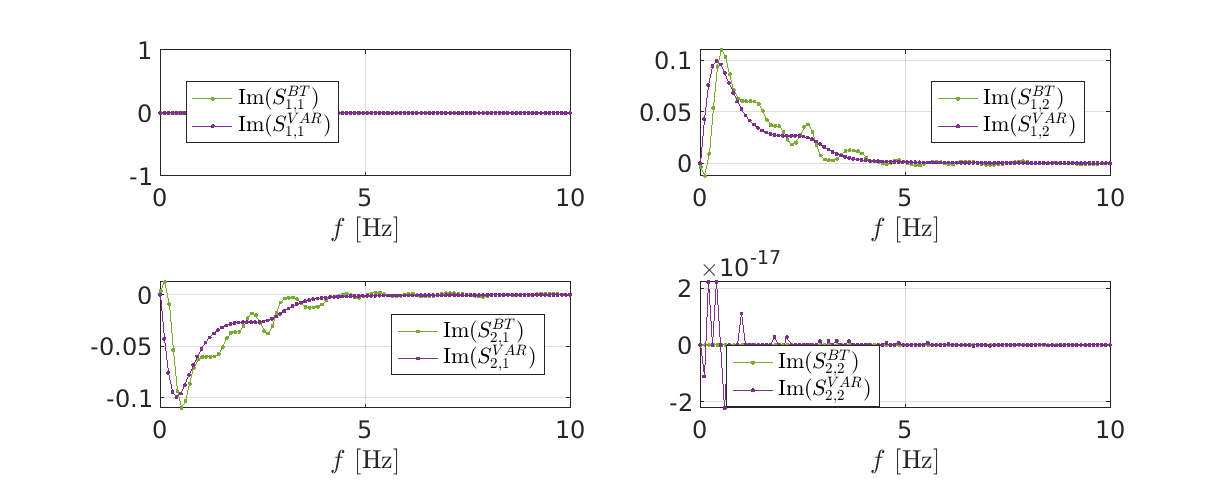


set(gcf,'position',figure_position)


% Quad-spectrum

figure(2)

for ii = 1:k

    for jj = 1:k

        subplot(k,k,(ii-1)*k+jj)

        x = CPSDM_BT.x_values;
        y = imag(squeeze(CPSDM_BT.y_values(ii,jj,:)));
        plot(x,y,'.-','color',color_estimated)

        hold on

        x = CPSDM_VAR.x_values;
        y = imag(squeeze(CPSDM_VAR.y_values(ii,jj,:)));
        plot(x,y,'.-','color',color_true)
    
        leg_BT = sprintf('Im$(S^{BT}_{%d,%d})$',ii,jj);
        leg_VAR = sprintf('Im$(S^{VAR}_{%d,%d})$',ii,jj);
        legend({leg_BT,leg_VAR},...
               'Interpreter','latex',...
               'Location','best')

        grid on
        xlabel('$f$ [Hz]','Interpreter','latex')
        set(gca,'fontsize',font_size)
        
    end

end

set(gcf,'position',figure_position)

## Remarks

- Note that the `CPSDM` is obtained by computing each spectrum $S_{ij}$ through function `get_S_data_BT`. You can refer to remarks detailed in tutorial *getting_S_from_data_through_BT.mlx* for further insights on this method.